# Exam January 11, 2019

## Exercise 1

clear
q = sym('q',[1 4])

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

syms d1 a4 L
dh = [ pi/2 0 d1 q(1);
       pi/2 0 0 q(2);
       pi/2 0 q(3) pi;
       0 a4 0 q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d_{1} & q_{1}\\ \frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & 0 & q_{3} & \pi \\ 0 & a_{4} & 0 & q_{4} \end{array}\right)$$


[T Tpartial] = getTransformationMatrix(dh,'alpha')

$$T = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1}\\ -\cos\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{4}\right) & -\cos\left(q_{2}+q_{4}\right) & 0 & d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right) \end{array}$$

Tpartial = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}



P = T(1:3,4)

$$P = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

q0 = [0  pi/2 L 0]

$$q0 = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & L & 0 \end{array}\right)$$

P4_0 = subs(P,q,q0)

$$P4\_0 = \left(\begin{array}{c} L\\ 0\\ d_{1}-a_{4} \end{array}\right)$$

close all
% Lengths just to test
len = 20

len = 20

len1 = 10

len1 = 10

% De Luca's approach
links = [
    Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
    Revolute('a', 0, 'alpha', pi/2 ,'d', 0);
    Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
    Revolute('a', len1, 'alpha', 0 ,'d', 0);
    ];

c600 = SerialLink(links);
%c600.teach([0  pi/2 10 0],'view','x')
c600.plot([0  pi/2 20 0],'view','x')

% My original approach --> Not the same result
close all
len = 20
len1 = 10
links = [
    Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
    Revolute('a', 0, 'alpha', -pi/2 ,'d', 0);
    Prismatic('qlim', [0 len],'alpha',pi/2,'theta',0);
    Revolute('a', len1, 'alpha', 0 ,'d', 0);
    ];

c600 = SerialLink(links);
c600.teach([0  pi/2 10 0],'view','x')
%c600.plot([0  pi/2 10 0],'view','x')

## Exercise 2

[Jp Jo] = getJacobian(dh,'RRPR','alpha')

rank(Jo)
%The generic rank of the lower Jac matrix is 2
J = [Jp;Jo];
J0 = subs(J,q,q0)
Jp0 = subs(Jp,q,q0)

qdot = sym('q',[4,1])
JpQdot = Jp0*qdot
[qdot01 qdot02 qdot03 qdot04] = solve(JpQdot == 0,qdot)

v1 = [1 0 1];
w1 = [0 0 -2];
V = [v1  w1]

[qdot1 qdot2 qdot3 qdot4] = solve(JpQdot == v1.')
null(JpQdot-v1)
%It is not possible to satisfy both v and w conditions
[qdot1 qdot2 qdot3 qdot4] = solve(J0*qdot == V)

J0.'
tau = J0.'*Fc

null(J0.')

## Exercise 3

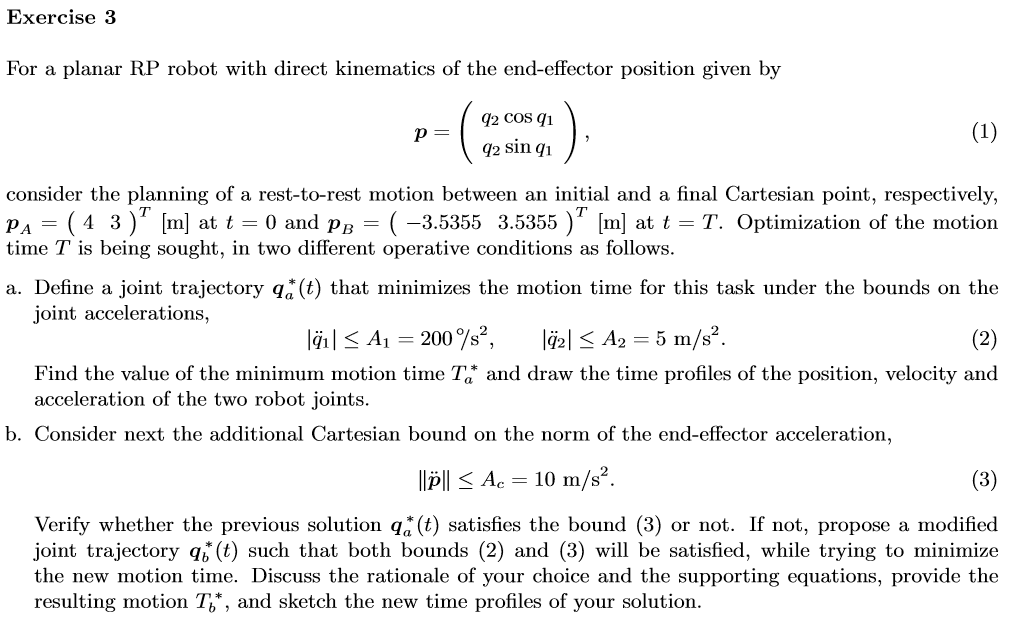

q = sym('q',[2,1])
p = [q(2)*cos(q(1)); q(2)*sin(q(1))]
pa = [4;3];
pb = [-3.5355 ;3.5355];

[q_a1 q_a2 ] = solve(p == pa, q);
eval([180/pi*q_a1 q_a2 ]);
[q_b1 q_b2 ] = solve(p == pb, q);
eval([180/pi*q_b1 q_b2 ]);

%We choose the solution with positive q2
pick = 2;
qA = eval([q_a1(pick); q_a2(pick)])
qB = eval([q_b1(pick); q_b2(pick)])

### Bang-bang profile

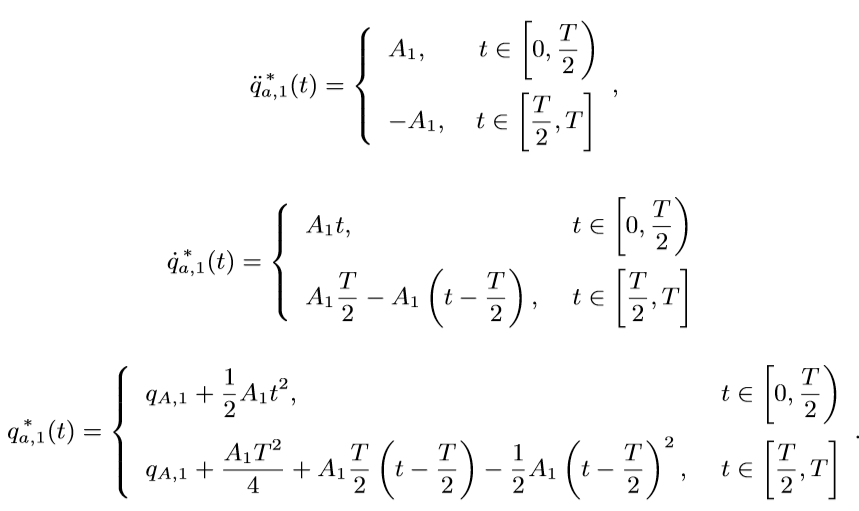

syms A1 T t t2nd
qppa1 = piecewise(0<=t<T/2, A1)
qppa2 = piecewise((T/2)<=t<T , -A1)
qppa = piecewise(0<=t<T/2, A1,qppa2)


qa1_all = sym(zeros(3,2));

% Define initial values
qa1_all(1,1) = A1;
qa1_all(1,2) = -A1;
for i = 2:3 % 1 not included. Initial values are defined by user.
    for j = 1:2
        if j == 1 % First interval
            val1 = int(qa1_all(i-1,1),t); % The integral of the previous magnitude. 
            qa1_all(i,j) = val1    ;
        end
        if j == 2 % Second interval 
            val2 = subs(val1,t,T/2) ... % Value of the function in the last interval, evaluated at its final value (T/2)
                 + expand(int(qa1_all(i-1,2),t2nd)); % Integral of the function in the last unit, same interval wrt t-T/2
            qa1_all(i,j) = subs(val2,t2nd,t-T/2)    ;
        end
    end
end

%% Create piecewise functions from the calculated terms

qa_piece = sym(zeros(3,1));

for i = 1:3
    qa_piece(i,1) = piecewise(0<=t<T/2, qa1_all(i,1), ...
                            (T/2)<=t<T, qa1_all(i,2)) 
end

%qastar = qa_piece(3)+ qA(1) % Sum initial value fo tge joint.
%t1 = subs(qastar,[t, A1],[T/2, 200])
% Have to put manually an equivalence to get the value


qa_piece(3) = qa_piece(3)+ qA(1)*180/pi


qa_piece1 = subs(qa_piece,[A1, T],[200, 1.401])
vpa(qa_piece1,4)

fplot(qa_piece1(1))
fplot(qa_piece1(2))
fplot(qa_piece1(3)) % There's a difference in the result.

syms q0 q1 v0 v1 t T a b c tao dq 

% Declare equation system for joint space trajectory

eq(1) = a+b+c == 1;
eq(2) = c == v0*T/dq;
eq(3) = 3*a+2*b+c == v1*T/dq;
eq.';
[as,bs,cs]=solve(eq.',[a b c])

qd = q0 + dq*(as*tao^3 + bs*tao^2 + cs*tao)

qa = subs(qd,[dq tao],[q1-q0 t/T])
qa = subs(qa,[v0 v1],[0 0])

%Initial conditions
% w is omega, for angular velocity
% acc is angular acceleration
w = diff(qa,t)
acc = diff(w,t)

%w0 = subs(w,t,0)
%wT = subs(w,t,T)

%acc0 = subs(acc,t,0)
%jerk = diff(acc,t)

%Evaluate the expression with the initial and final joint values
%The f subscript is used to differenciate a from the point. q_a = f

acc_f = subs(acc,[q0 q1],[qA(1) qB(1)])
%Derivate to get the maximum point of accelerarion, and apply the boundary
jerk_f = diff(acc_f,t)
solve(jerk_f == 0,t)

%q0 = 